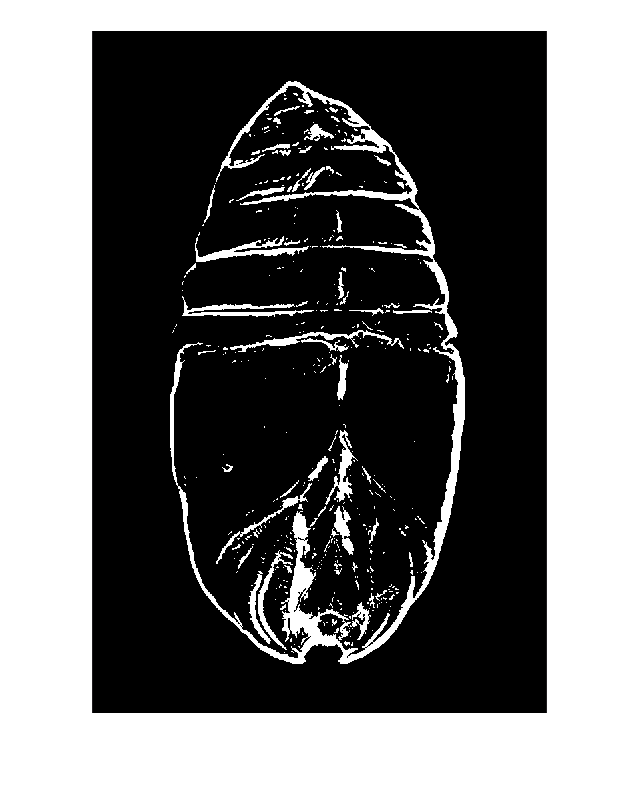

test=rgb2gray(imread('betterer.jpg'));
W1= gradientweight(test, 3, 'RolloffFactor', 4, 'WeightCutoff', .22);
mask1=false(size(test));
mask1(1,1)=true;
segtest1=imcomplement(imsegfmm(W1,mask1,0.24));
imclearborder(segtest1);
imshow(segtest1)

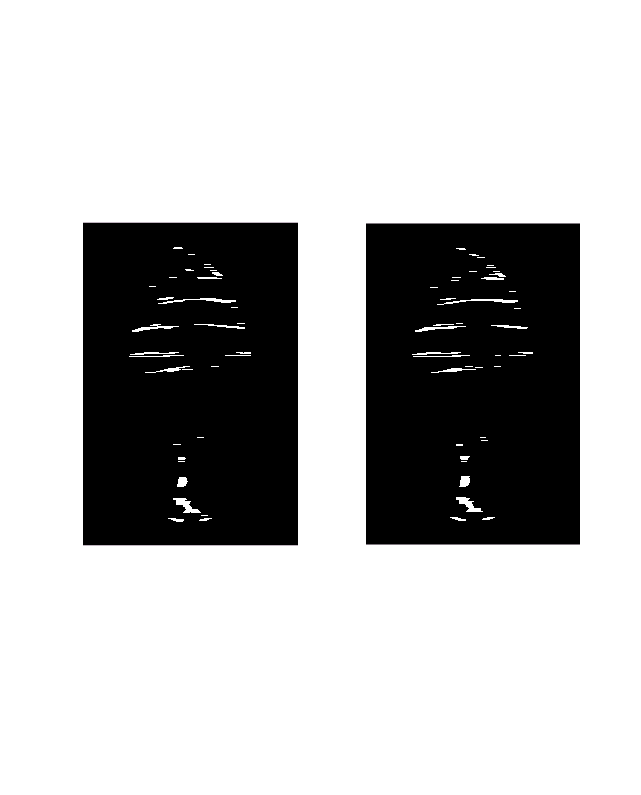

SE=strel('line',20,0);
segtest1=imopen(segtest1,SE);
subplot(1,2,1)
imshow(segtest1);
SE1=strel('rectangle',[1,20]);
segtest1=imclose(segtest1,SE1);
subplot(1,2,2)
imshow(segtest1);

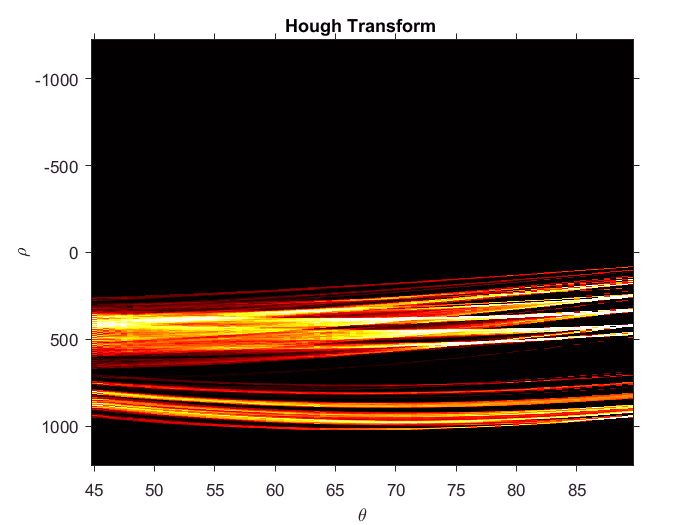

[H,T,R] = hough(segtest1,'Theta',45:0.5:89.5);
P=houghpeaks(H,8);
figure
imshow(imadjust(mat2gray(H)),'XData',T,'YData',R,...
   'InitialMagnification','fit');
title('Hough Transform ');
xlabel('\theta'), ylabel('\rho');
axis on, axis normal;
colormap(hot)

lines = houghlines(segtest1,T,R,P,'MinLength',10,'FillGap',70);
figure, imshow(segtest1), hold on

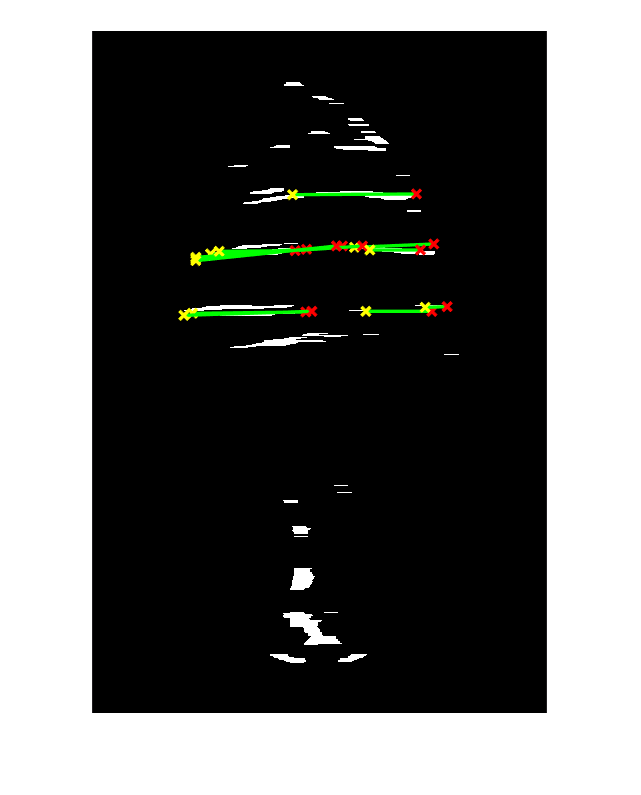

max_len = 0;
for k = 1:length(lines)
   xy = [lines(k).point1; lines(k).point2];
   plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');

   % Plot beginnings and ends of lines
   plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
   plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');

   % Determine the endpoints of the longest line segment
   len = norm(lines(k).point1 - lines(k).point2);
   if ( len > max_len)
      max_len = len;
      xy_long = xy;
   end
end